%Simon Yoon ECE300PS01

clear
clc
close all;

## Frequency Domain

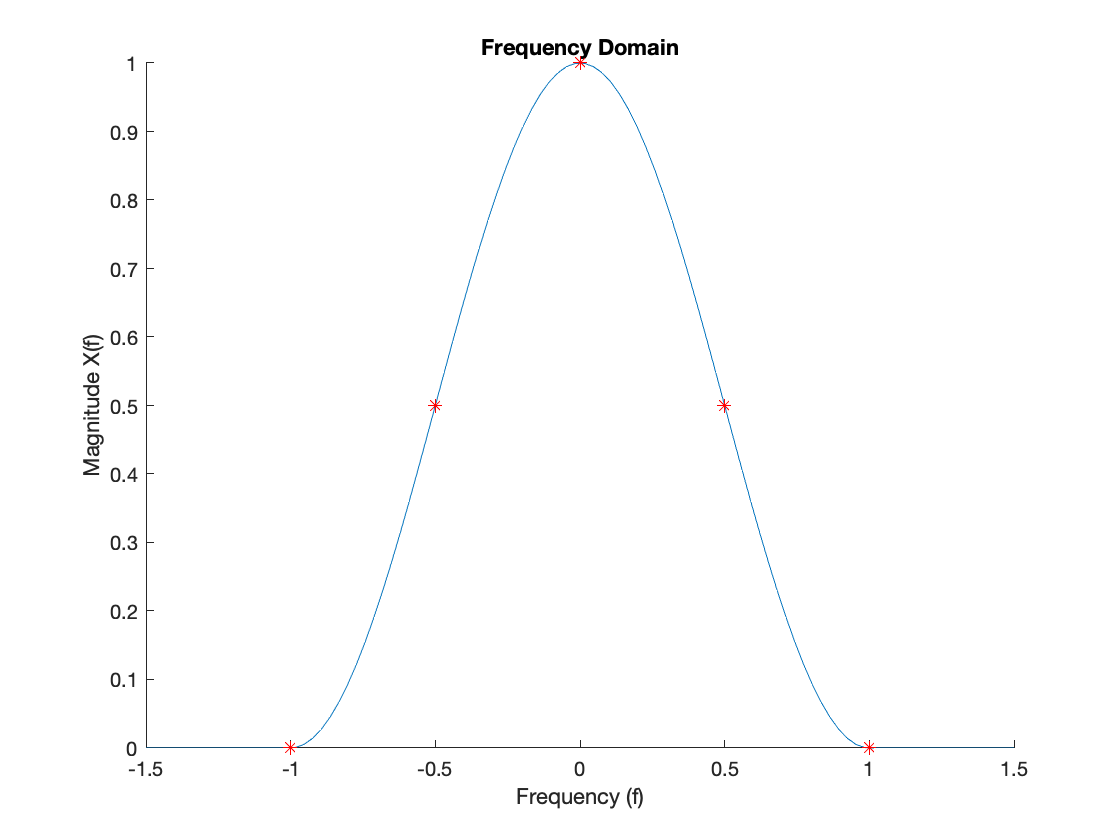

f = linspace(-1.5, 1.5, 100);
A = 1;
W = 1;

xF = (A/(2*W))*(1 + cos(pi.*f/W)).*rectangularPulse(-1/2,1/2, f.*(1/(2*W)));

figure(1);
hold on;
plot(f, xF);
plot(.5, .5, 'r*', -.5, .5, 'r*', 1, 0, 'r*', -1, 0, 'r*', 0, 1, 'r*');
title("Frequency Domain")
ylabel("Magnitude X(f)")
xlabel("Frequency (f)")

## Time Domain

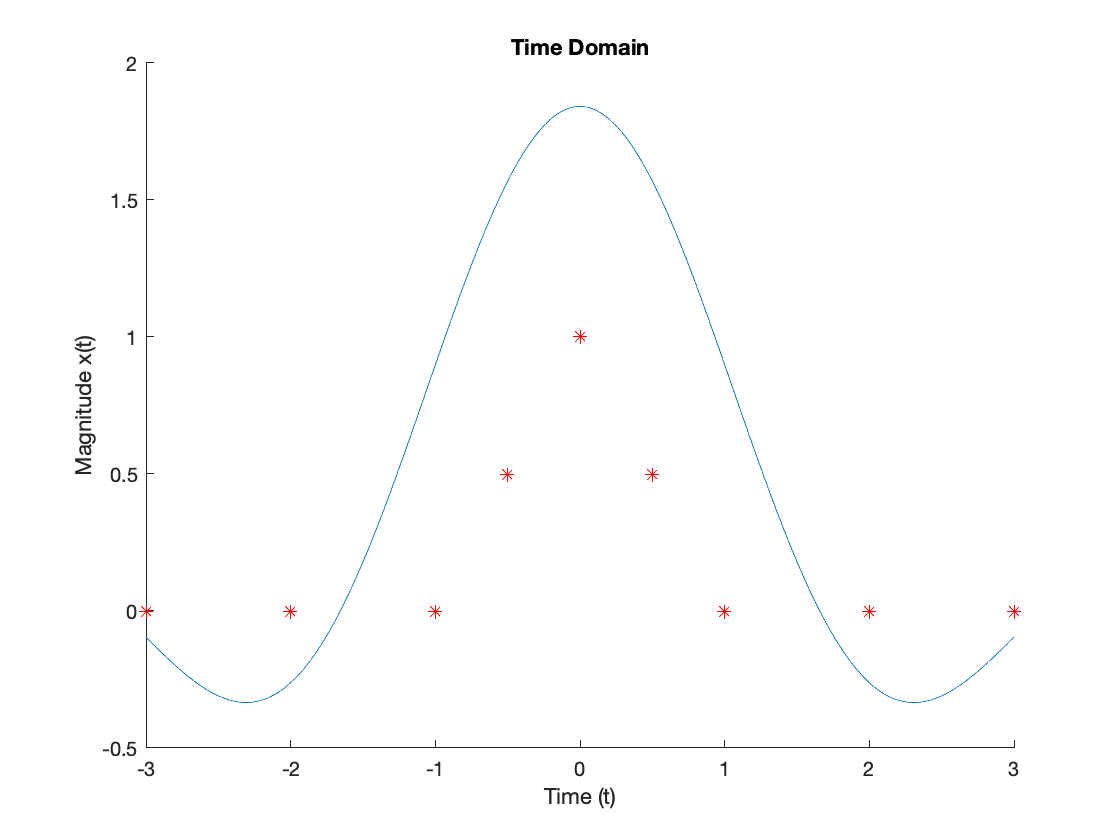

t = linspace(-3, 3, 1000);

xT = A*sin(2*W*t)./(2*W*t) + 1/2*A*sin(2*W*(t - (1/(2*W))))./(2*W*(t - (1/(2*W)))) + 1/2*A*sin(2*W*(t + (1/(2*W))))./(2*W*(t + (1/(2*W))));

figure(2);
hold on;
plot(t, xT);
plot(.5, .5, 'r*', -.5, .5, 'r*', 1, 0, 'r*', -1, 0, 'r*', 2, 0, 'r*', -2, 0, 'r*',  3, 0, 'r*', -3, 0, 'r*', 0, 1, 'r*');
title("Time Domain")
ylabel("Magnitude x(t)")
xlabel("Time (t)")